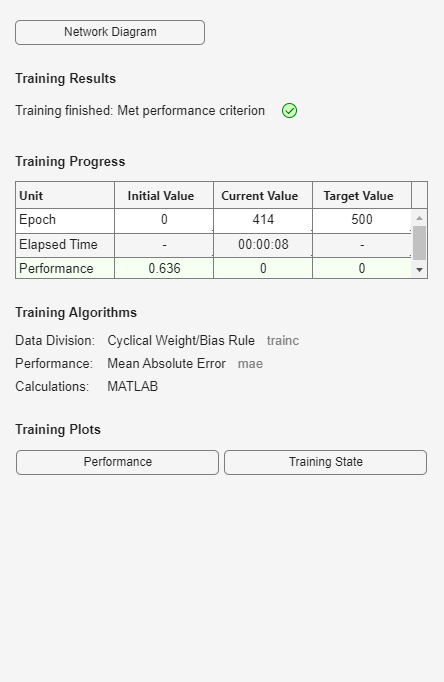

%三分类感知器模型
clear                                       %清理内存
UNDP3                                       %将work文件夹的数据导入内存
X=[C1;C2;C3;S];                             %全部变量合并为一个矩阵
n=length([C1;C2;C3]);                       %训练样本长度
m=length(S);                                %待判样本长度
A=mean(X);                                  %计算全部变量的均值
Mt=A(ones(n,1),:);                          %均值向量平移为矩阵
Ms=A(ones(m,1),:);                          %均值向量平移为矩阵
P=([C1;C2;C3]./Mt)';                        %将三个子样本的数据合并为训练样本
G1=[zeros(length(C1),1); zeros(length(C2),1); ones(length(C3),1)];
                                            %定义第一个分类变量表示的类别数组
G2=[zeros(length(C1),1); ones(length(C2),1); zeros(length(C3),1)]; 
                                            %定义第二个顺序变量表示的类别数组
T=[G1,G2]';                                 %三分类的双目标输出
Q=(S./Ms)';                                 %待判样品信息
net=newp(minmax(P),2);                      %构建一个双输出感知器网络
net.trainParam.epochs=500;                  %指定最大训练次数
net=train(net,P,T);                         %网络训练

Yp=sim(net,P)                               %训练样品的预报结果

Yp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0


Y=sim(net,Q)                                %给出待判样品的仿真结果

Y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     1     1     0     1     0     0     1     1     1     0     0     0     0
